       I=imread('pout2.png');
       mapping=getmapping(8,'u2'); 

For Matlab version 8.0 and higher


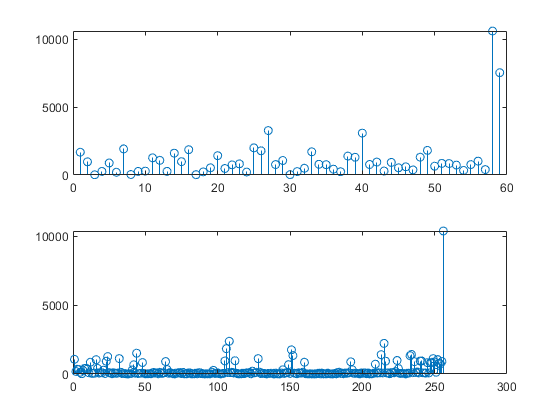

       H1=lbpf(I,1,8,mapping,'h'); %LBP histogram in (8,1) neighborhood
                                  %using uniform patterns
       subplot(2,1,1),stem(H1);

       H2=lbpf(I);
       subplot(2,1,2),stem(H2);


       SP=[-1 -1; -1 0; -1 1; 0 -1; -0 1; 1 -1; 1 0; 1 1];
       resultset5=lbpf(I,SP,0,'i'); %LBP code image using sampling points in SP
                           %and no mapping. Now H2 is equal to histogram
                           %of I2.





function result = lbpf(varargin) % image,radius,neighbors,mapping,mode)
% Version 0.3.3
% Authors: Marko Heikkil?and Timo Ahonen

% Changelog
% Version 0.3.2: A bug fix to enable using mappings together with a
% predefined spoints array
% Version 0.3.1: Changed MAPPING input to be a struct containing the mapping
% table and the number of bins to make the function run faster with high number
% of sampling points. Lauge Sorensen is acknowledged for spotting this problem.


% Check number of input arguments.
error(nargchk(1,5,nargin));

image=varargin{1};
d_image=double(image);

if nargin==1
    spoints=[-1 -1; -1 0; -1 1; 0 -1; -0 1; 1 -1; 1 0; 1 1];
    neighbors=8;
    mapping=0;
    mode='h';
end

if (nargin == 2) && (length(varargin{2}) == 1)
    error('Input arguments');
end

if (nargin > 2) && (length(varargin{2}) == 1)
    radius=varargin{2};
    neighbors=varargin{3};
    
    spoints=zeros(neighbors,2);

    % Angle step.
    a = 2*pi/neighbors;
    
    for i = 1:neighbors
        spoints(i,1) = -radius*sin((i-1)*a);
        spoints(i,2) = radius*cos((i-1)*a);
    end
    
    if(nargin >= 4)
        mapping=varargin{4};
        if(isstruct(mapping) && mapping.samples ~= neighbors)
            error('Incompatible mapping');
        end
    else
        mapping=0;
    end
    
    if(nargin >= 5)
        mode=varargin{5};
    else
        mode='h';
    end
end

if (nargin > 1) && (length(varargin{2}) > 1)
    spoints=varargin{2};
    neighbors=size(spoints,1);
    
    if(nargin >= 3)
        mapping=varargin{3};
        if(isstruct(mapping) && mapping.samples ~= neighbors)
            error('Incompatible mapping');
        end
    else
        mapping=0;
    end
    
    if(nargin >= 4)
        mode=varargin{4};
    else
        mode='h';
    end   
end

% Determine the dimensions of the input image.
[ysize xsize] = size(image);



miny=min(spoints(:,1));
maxy=max(spoints(:,1));
minx=min(spoints(:,2));
maxx=max(spoints(:,2));

% Block size, each LBP code is computed within a block of size bsizey*bsizex
bsizey=ceil(max(maxy,0))-floor(min(miny,0))+1;
bsizex=ceil(max(maxx,0))-floor(min(minx,0))+1;

% Coordinates of origin (0,0) in the block
origy=1-floor(min(miny,0));
origx=1-floor(min(minx,0));

% Minimum allowed size for the input image depends
% on the radius of the used LBP operator.
if(xsize < bsizex || ysize < bsizey)
  error('Too small input image. Should be at least (2*radius+1) x (2*radius+1)');
end

% Calculate dx and dy;
dx = xsize - bsizex;
dy = ysize - bsizey;

% Fill the center pixel matrix C.
C = image(origy:origy+dy,origx:origx+dx);
d_C = double(C);

bins = 2^neighbors;

% Initialize the result matrix with zeros.
result=zeros(dy+1,dx+1);

%Compute the LBP code image

for i = 1:neighbors
  y = spoints(i,1)+origy;
  x = spoints(i,2)+origx;
  % Calculate floors, ceils and rounds for the x and y.
  fy = floor(y); cy = ceil(y); ry = round(y);
  fx = floor(x); cx = ceil(x); rx = round(x);
  % Check if interpolation is needed.
  if (abs(x - rx) < 1e-6) && (abs(y - ry) < 1e-6)
    % Interpolation is not needed, use original datatypes
    N = image(ry:ry+dy,rx:rx+dx);
    D = N >= C; 
  else
    % Interpolation needed, use double type images 
    ty = y - fy;
    tx = x - fx;

    % Calculate the interpolation weights.
    w1 = roundn((1 - tx) * (1 - ty),-6);
    w2 = roundn(tx * (1 - ty),-6);
    w3 = roundn((1 - tx) * ty,-6) ;
    % w4 = roundn(tx * ty,-6) ;
    w4 = roundn(1 - w1 - w2 - w3, -6);
            
    % Compute interpolated pixel values
    N = w1*d_image(fy:fy+dy,fx:fx+dx) + w2*d_image(fy:fy+dy,cx:cx+dx) + ...
w3*d_image(cy:cy+dy,fx:fx+dx) + w4*d_image(cy:cy+dy,cx:cx+dx);
    N = roundn(N,-4);
    D = N >= d_C; 
  end  
  % Update the result matrix.
  v = 2^(i-1);
  result = result + v*D;
end

%Apply mapping if it is defined
if isstruct(mapping)
    bins = mapping.num;
    for i = 1:size(result,1)
        for j = 1:size(result,2)
            result(i,j) = mapping.table(result(i,j)+1);
        end
    end
end

if (strcmp(mode,'h') || strcmp(mode,'hist') || strcmp(mode,'nh'))
    % Return with LBP histogram if mode equals 'hist'.
    result=hist(result(:),0:(bins-1));
    if (strcmp(mode,'nh'))
        result=result/sum(result);
    end
else
    %Otherwise return a matrix of unsigned integers
    if ((bins-1)<=intmax('uint8'))
        result=uint8(result);
    elseif ((bins-1)<=intmax('uint16'))
        result=uint16(result);
    else
        result=uint32(result);
    end
end

end

function x = roundn(x, n)

narginchk(2, 2)
validateattributes(x, {'single', 'double'}, {}, 'ROUNDN', 'X')
validateattributes(n, ...
    {'numeric'}, {'scalar', 'real', 'integer'}, 'ROUNDN', 'N')

if n < 0
    p = 10 ^ -n;
    x = round(p * x) / p;
elseif n > 0
    p = 10 ^ n;
    x = p * round(x / p);
else
    x = round(x);
end

end

function [ output_args ] = Untitled4( input_args )
%UNTITLED4 Summary of this function goes here
%   Detailed explanation goes here


end

function mapping = getmapping(samples,mappingtype)

disp('For Matlab version 8.0 and higher');

table = 0:2^samples-1;
newMax  = 0; %number of patterns in the resulting LBP code
index   = 0;

if strcmp(mappingtype,'u2') %Uniform 2
    newMax = samples*(samples-1) + 3;
    for i = 0:2^samples-1

        i_bin = dec2bin(i,samples);
        j_bin = circshift(i_bin',-1)';              %circularly rotate left
        numt = sum(i_bin~=j_bin);                   %number of 1->0 and
                                                    %0->1 transitions
                                                    %in binary string
                                                    %x is equal to the
                                                    %number of 1-bits in
                                                    %XOR(x,Rotate left(x))

        if numt <= 2
            table(i+1) = index;
            index = index + 1;
        else
            table(i+1) = newMax - 1;
        end
    end
end

if strcmp(mappingtype,'ri') %Rotation invariant
    tmpMap = zeros(2^samples,1) - 1;
    for i = 0:2^samples-1
        rm = i;
    
        r_bin = dec2bin(i,samples);

        for j = 1:samples-1

            r = bin2dec(circshift(r_bin',-1*j)'); %rotate left    
            if r < rm
                rm = r;
            end
        end
        if tmpMap(rm+1) < 0
            tmpMap(rm+1) = newMax;
            newMax = newMax + 1;
        end
        table(i+1) = tmpMap(rm+1);
    end
end

if strcmp(mappingtype,'riu2') %Uniform & Rotation invariant
    newMax = samples + 2;
    for i = 0:2^samples - 1
        
        i_bin =  dec2bin(i,samples);
        j_bin = circshift(i_bin',-1)';
        numt = sum(i_bin~=j_bin);
  
        if numt <= 2
            table(i+1) = sum(bitget(i,1:samples));
        else
            table(i+1) = samples+1;
        end
    end
end

mapping.table=table;
mapping.samples=samples;
mapping.num=newMax;
end